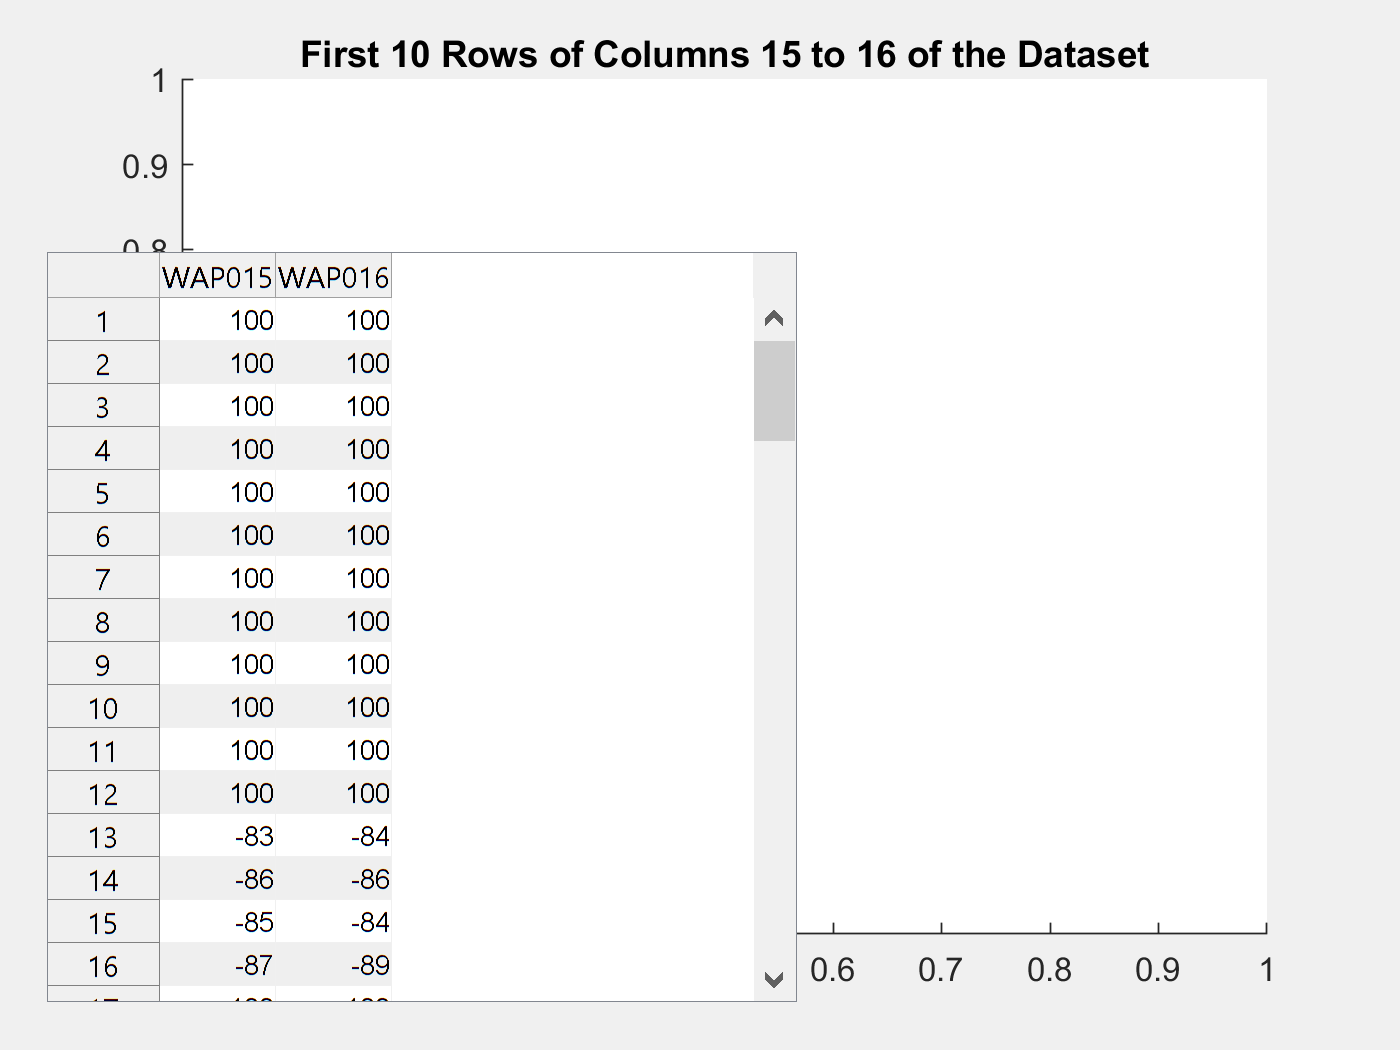

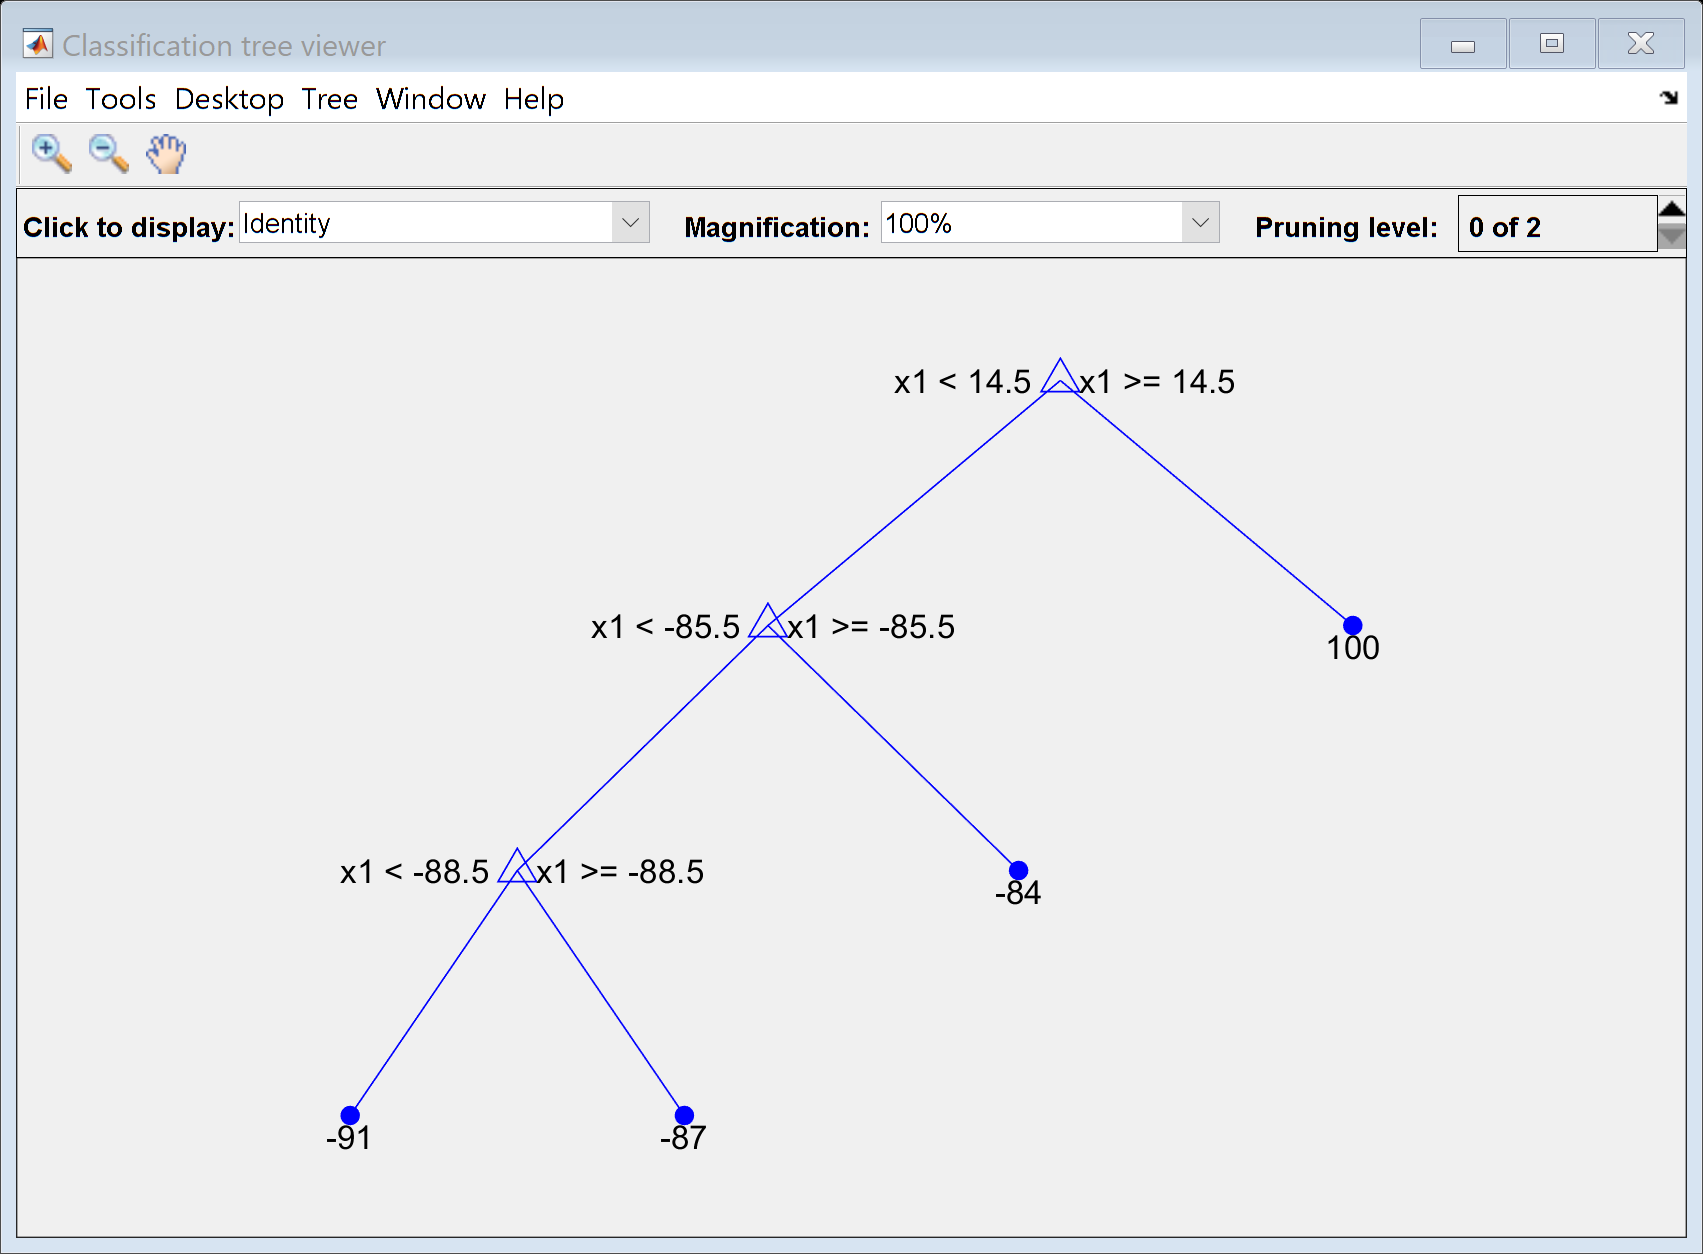

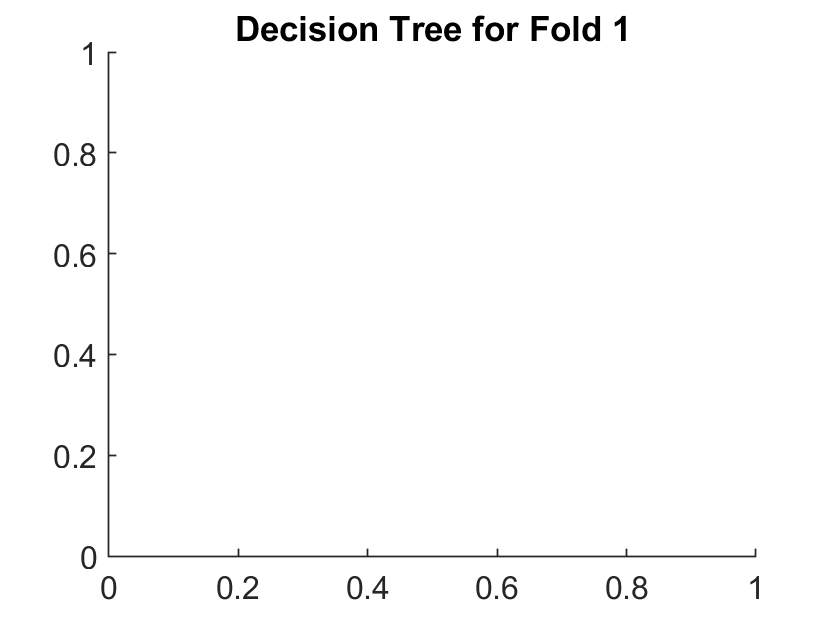

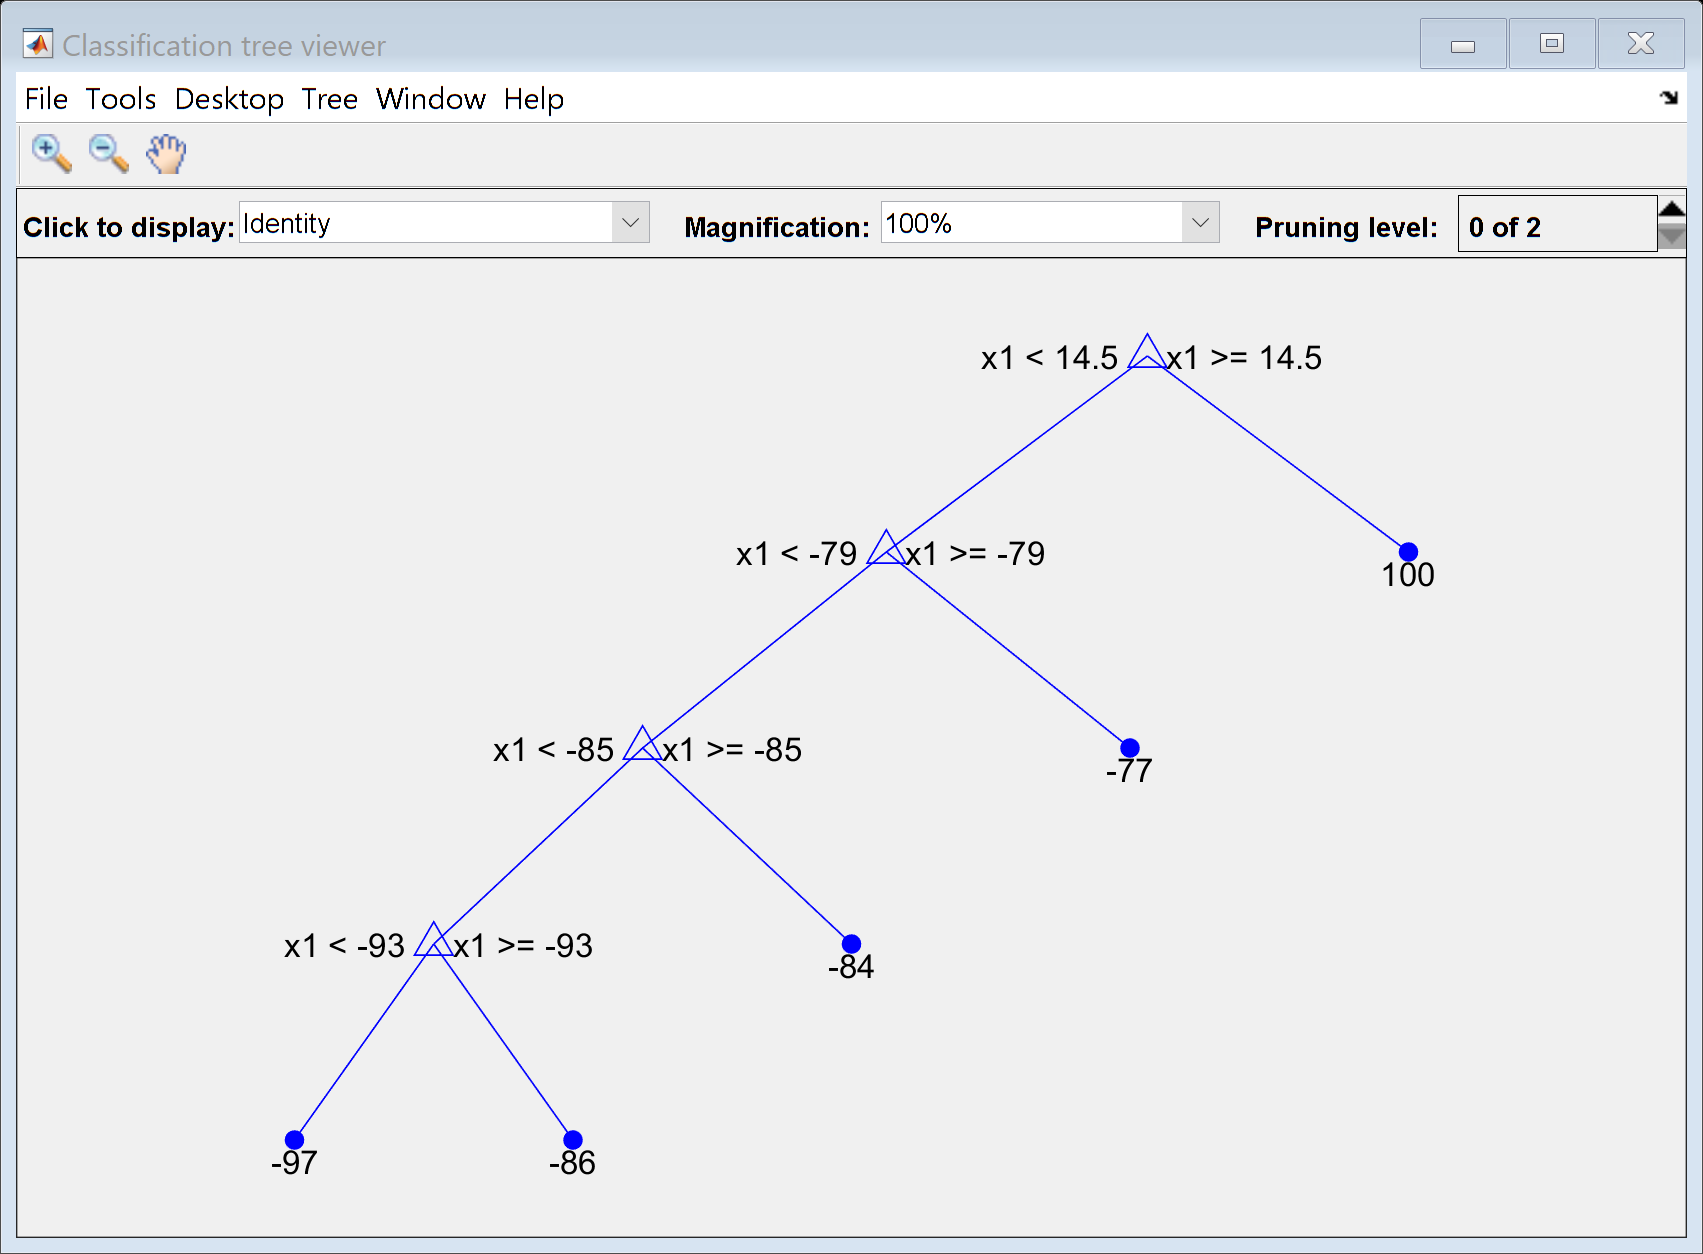

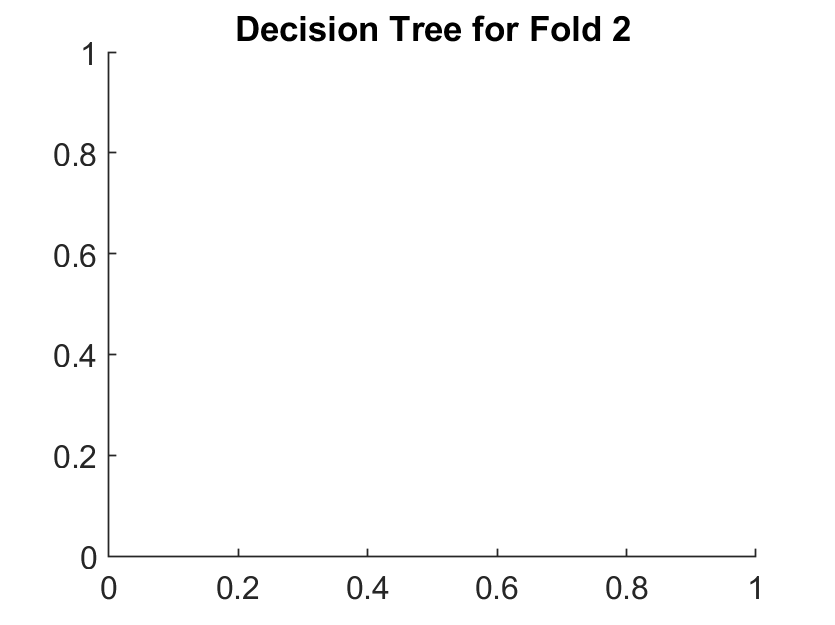

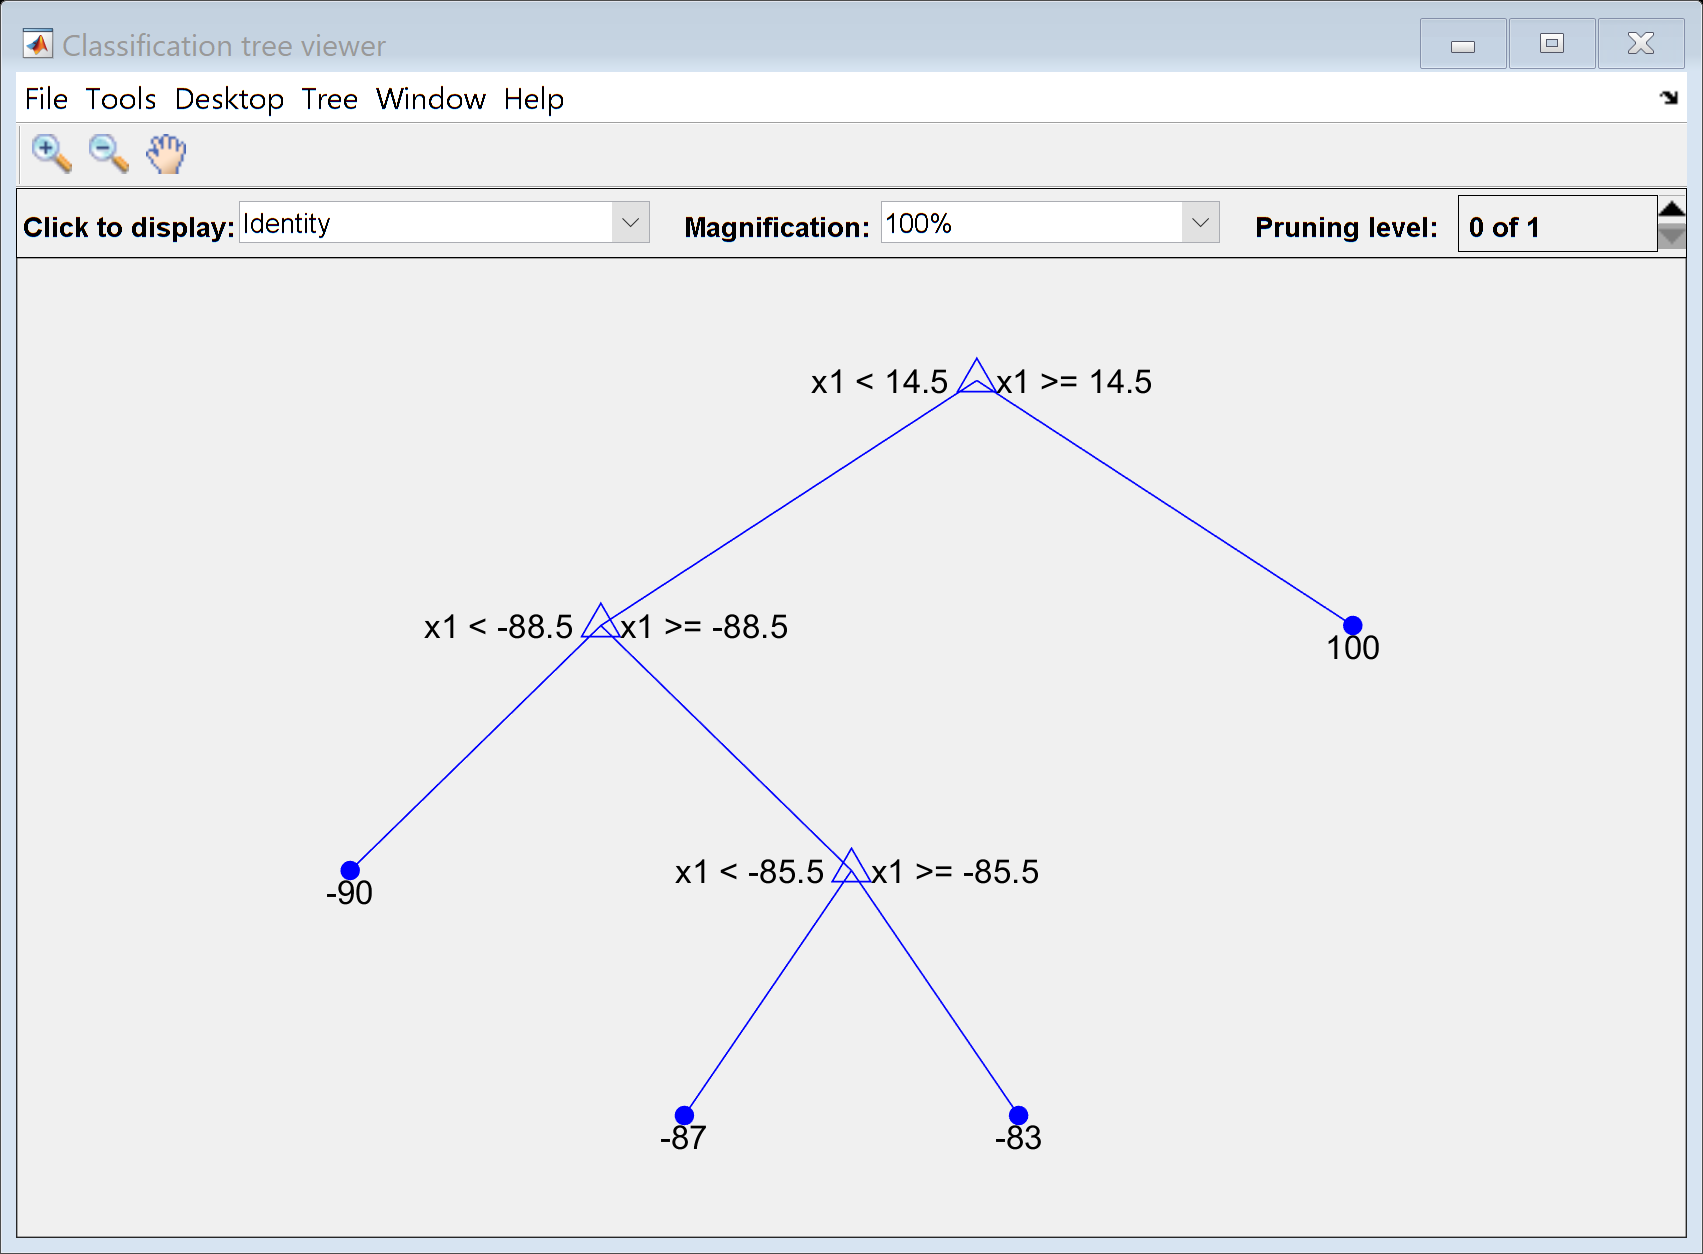

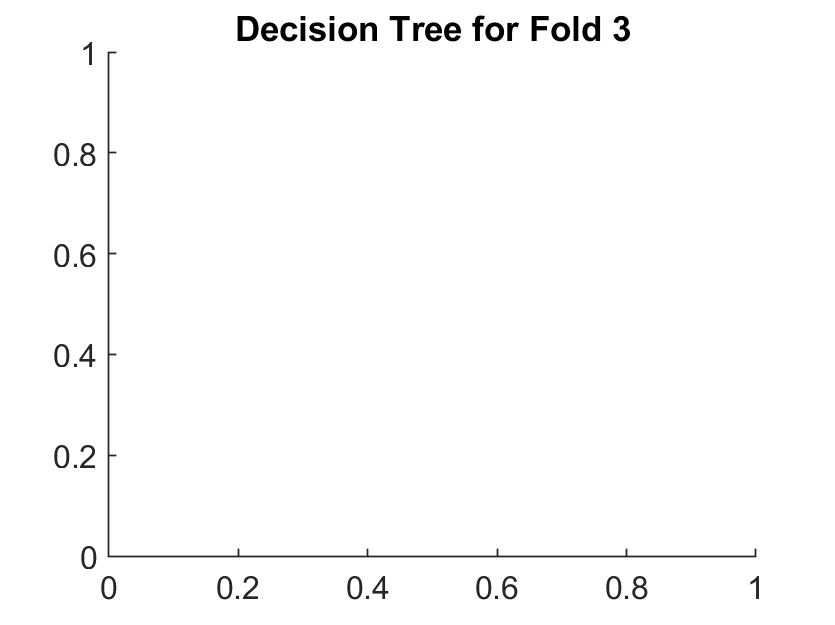

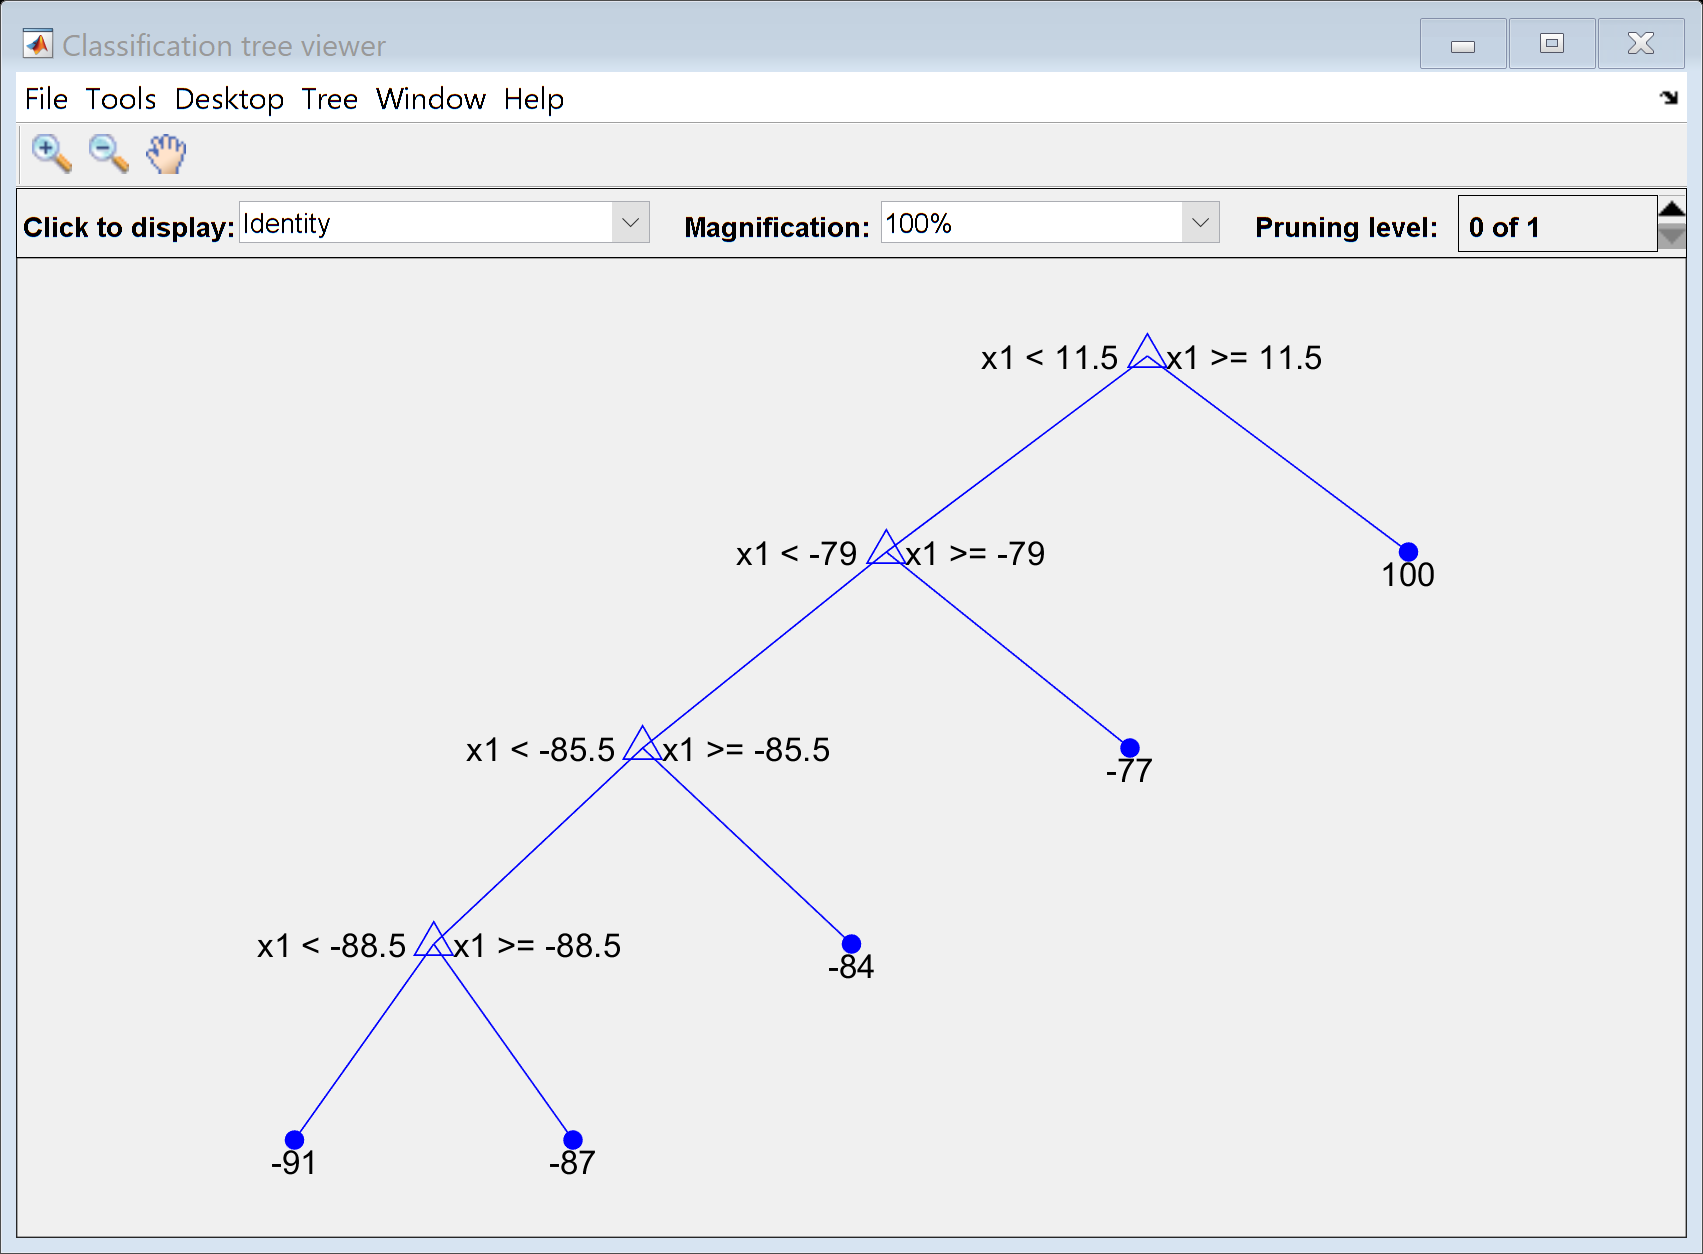

filePath = fullfile(getenv('USERPROFILE'), 'Desktop', 'trainingData.csv');
data = readtable(filePath);
selectedData = data(1:100, 15:16);
figure;
uitable('Data', selectedData(1:100, :).Variables, 'ColumnName', selectedData.Properties.VariableNames);
title('First 10 Rows of Columns 15 to 16 of the Dataset');
saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'SelectedDatasetHead.png'));
features = selectedData(:, 1:end-1);  
target = selectedData(:, end);        
X = table2array(features);
Y = table2array(target);
if iscell(Y)
    Y = categorical(Y);
end

k = 5;
cv = cvpartition(height(selectedData), 'KFold', k);

accuracies = zeros(k, 1);
for i = 1:k
    trainIdx = training(cv, i);
    testIdx = test(cv, i);
    XTrain = X(trainIdx, :);
    YTrain = Y(trainIdx, :);
    XTest = X(testIdx, :);
    YTest = Y(testIdx, :);

    treeModel = fitctree(XTrain, YTrain, 'MinLeafSize', 1, 'MaxNumSplits', 20);
    YPred = predict(treeModel, XTest);
    accuracies(i) = sum(YPred == YTest) / numel(YTest);

    figure;
    view(treeModel, 'Mode', 'graph');
    title(sprintf('Decision Tree for Fold %d', i));
    saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', sprintf('DecisionTreeFold%d.png', i)));
end


avgAccuracy = mean(accuracies);
fprintf('Average Accuracy: %.2f%%\n', avgAccuracy * 100);

Average Accuracy: 75.00%



treeModel = fitctree(X, Y, 'MinLeafSize', 1, 'MaxNumSplits', 20);
YPred = predict(treeModel, X);
accuracy = sum(YPred == Y) / numel(Y);
fprintf('Accuracy on entire dataset: %.2f%%\n', accuracy * 100);

Accuracy on entire dataset: 83.00%


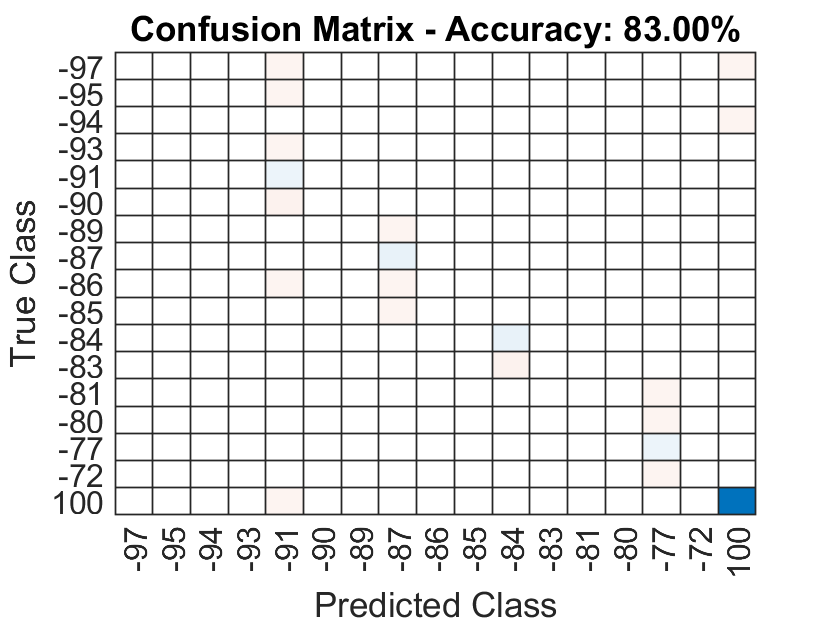


figure;
confusionchart(Y, YPred);
title(sprintf('Confusion Matrix - Accuracy: %.2f%%', accuracy * 100));
saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'ConfusionMatrixTree.png'));

Mean Error: -2.04


Median Error: 0.00


Standard Deviation of Error: 33.73


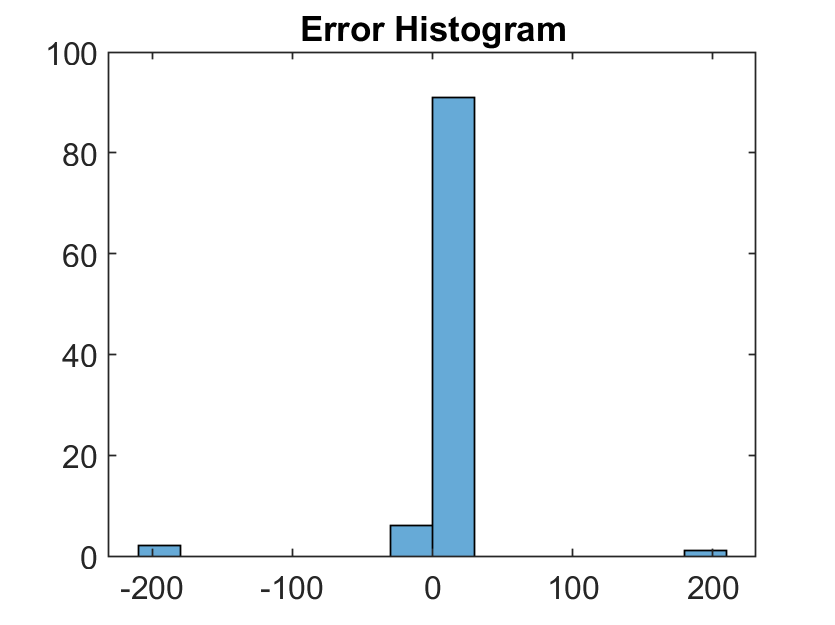


if ~iscategorical(Y)
    errors = Y - YPred;
    meanError = mean(errors);
    medianError = median(errors);
    stdError = std(errors);
    
    fprintf('Mean Error: %.2f\n', meanError);
    fprintf('Median Error: %.2f\n', medianError);
    fprintf('Standard Deviation of Error: %.2f\n', stdError);
    
    figure;
    histogram(errors);
    title('Error Histogram');
    saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'ErrorHistogramTree.png'));
end